Data Transmitted 

load data.mat
fc = 2000; %2kHz;
fs = 44.1 * 10^3;
time = linspace(0,1,length(y));

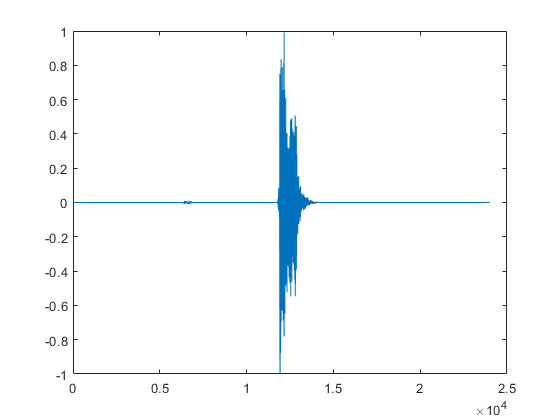

figure();
plot(h_received);

Estimate Channel;

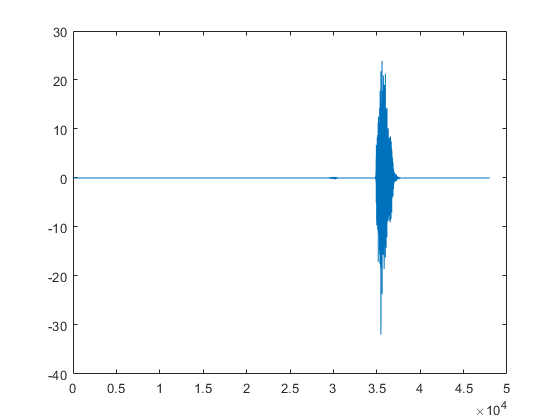

h_xcorr = xcorr(h_received, n);
plot(h_xcorr);

Multiply by cos:

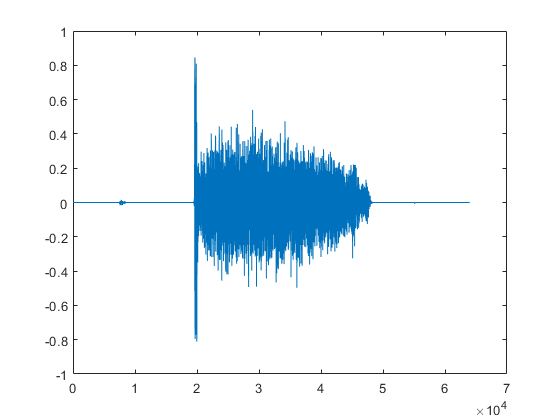

cos_y = y.*cos(2*pi*fc*time.');
figure();
plot(cos_y);

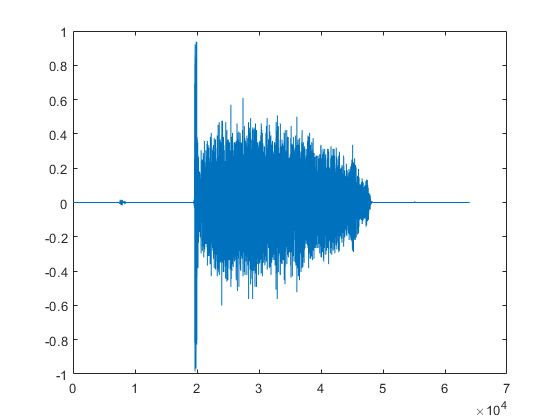

figure();
plot(y);

LPF

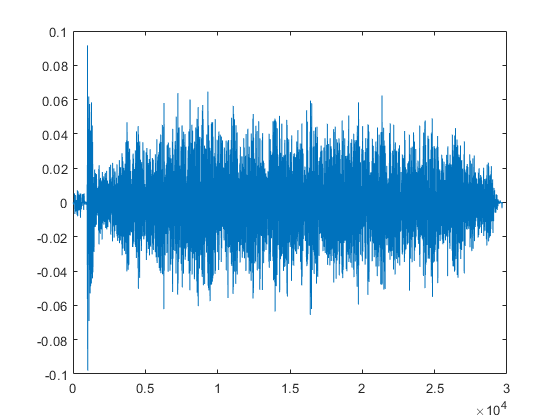


filter_y = nonzeros(lowpass(cos_y, 1.5^5, fs));
figure();
plot(filter_y);


binary_y = zeros(1,length(filter_y));
binary_y(filter_y < 0) = 0;
binary_y(filter_y > 0) = 1;

info = vec2mat(binary_y,7);
% res = bin2dec(info(1,:))

Error using bin2dec (line 36)
Input must be a character vector.